# PAX1000 polariméter LTM adatsorainak feldolgozása konstans értékek esetén

A ; tagolású .csv fájlok elérési út és fájlnév (vagy fájlnévben használt indexelés) alapján azonosíthatók. A fájlnevet kiterjesztés nélkül kell megadni. Ki kell választani a vizsgálandó mennyiséget. Hibás hívás esetén hibaüzenet sorolja fel a lehetséges választásokat. Az algoritmus megkísérli a választott mérési eredménysort oszcilláló mérési eredmény esetén alsó és felső becslők sorába rendezni. Eközben nagyon kiugró és nagy jitterrel keletkezett eredményeket kiszűr. Működés közben ábrázolja az eredményeket. Konstans érték mérése esetén többnyire célravezető a becslő pontos leolvasásához a megfelelő adatsor módusainak számítása. Ez a szkript a feldolgozott adatok és az így leolvasott értékek tárolására is szolgál.

## Fájlok kijelölése

A `path` táblázat az LTM eredményfájljaihoz tartozó elérési útvonalakat tartalmazza,  `indices` a fájlneveket (mint indexsztringeket), `aux` minden egyes fájlnév után a megfelelő `indices`-érték után beillesztett sztring (de nem a .csv kiterjesztés).

path=cell(1,14);
indices=cell(14,1);
aux='';
path{1}='meas1.2/1-5050/';
path{2}='meas1.2/2A-9010/';
path{3}='meas1.2/2B-9010/';
path{4}='meas1.2/2C-9010/';
path{5}='meas1.2/2C-9010/';
path{6}='meas1.2/3-9901/';
path{7}='meas1.3/0PBS-A/';
path{8}='meas1.3/0PBS-B/';
path{9}='meas1.3/0PBS-C/';
path{10}='meas1.3/0PBS-D/';
path{11}='meas1.2/4A-FM/';
path{12}='meas1.2/4B-FM/';
path{13}='meas1.3/1FM-A/';
path{14}='meas1.3/1FM-B/';
indices(1,1:12)={'1-IJ','2-IS','3-IT','4-JS','5-JT','6-ST','7-JI','8-SI',...
    '9-TI','10-SJ','11-TJ','12-TS'};
indices(2,1:6)={'1-IS','2-IT','3-ST','4-SI','5-TI','6-TS'};
indices(3,1:6)={'1-IS','2-IT','3-ST','4-SI','5-TI','6-TS'};
indices(4,1:6)={'1-IS','2-IT','3-ST','4-SI','5-TI','6-TS'};
indices(5,1:6)={'1-IS','2-IT','3-ST','4-SI','5-TI','6-TS'};
indices(6,1:6)={'1-IS','2-IT','3-ST','4-SI','5-TI','6-TS'};
indices(7,1:7)={'1-31','2-32a','2-32b','3-12','4-13','5-23','6-21'};
indices(8,1:7)={'1-31','2-32a','2-32b','3-12','4-13','5-23','6-21'};
indices(9,1:6)={'1-31','2-32a','2-32b','3-12','4-13','5-23'};
indices(10,1:7)={'1-31','2-32a','2-32b','3-12','4-13','5-23','6-21'};
indices(11,1:2)={'D12','D21'};
indices(12,1:2)={'D12','D21'};
indices(13,1:2)={'D12','D21'};
indices(14,1:2)={'D12','D21'};

## Vizsgált mennyiség kiválasztása

A példa kedvéért a dBm-ben mért optikai teljesítménymérést vizsgáljuk.

inputname='logp';

## Szűrési paraméterek megadása

A `trend` változó a szűrés optimalizálásához szükséges, -1 monoton csökkenő, 0 konstans és 1 monoton növekvő mért mennyiség esetén. A `tolerance` paraméter azt jellemzi, a számítási pontosság melletti legkisebb érték hányszorosánál nagyobb ugrás tekintendő az eredmény oszcillációja hatásának; logaritmikus teljesítménymérés esetén tipikusan 3 alatti érték. A `pround` a számítási pontosságot jellemző parraméter: ennyi tizedesjegyre lesznek kerekítve a mérési adatok.

trend=0;
tolerance=1;
pround=3;

## A `createparam` függvény hívása

A változók az itt bemutatott létrehozás sorrendjében adhatók át az adatfeldolgozó függvénynek. A kimenetet a következőképp ajánlott tárolni: `unprocessed` táblázat tartalmazza a nyers adatsort, `tv` táblázat külön a mérések rögzítésének időpontját az LTM indításához képest ms-ban, `processed` táblázat a szűrt, alsó és felső becslő adatsorba rendezett értékeket, `tvp` táblázat a szűrt értékekhez tartozó mérési időpontokat a jitter-mentes mintavételezés időpontjaihoz igazítva (ahol elég kicsi volt a tényleges mérési időpontok eltérése a jitter-mentes mintavételezéstől).

unprocessed=cell(1,14);
tv=cell(1,14);
processed=cell(1,14);
tvp=cell(1,14);

Az adatfeldolgozás során keletkező ábrák segítségével érdemes próbálkozni különböző `tolerance` értékek választásával, ez időnként kiküszöböli az esetlegesen hibás feldolgozást.

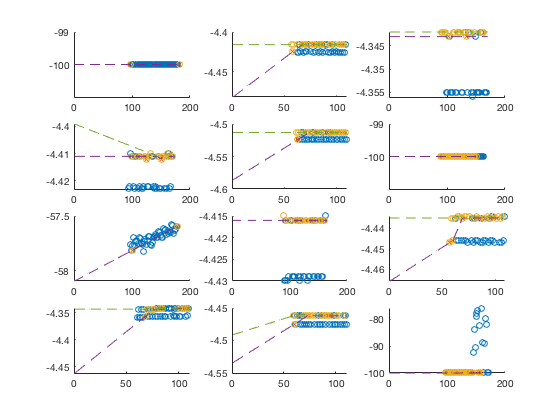

i=1;
[unprocessed{i},tv{i},processed{i},tvp{i}]=createparam(path(i),indices(i,...
    1:lastnonempty(indices(i,:))), aux, inputname, trend, tolerance,pround);

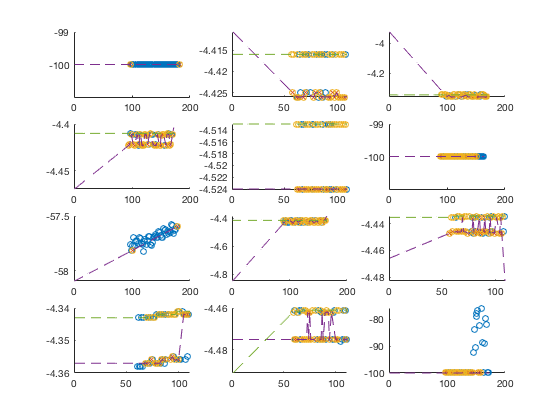

tolerance=1.79;
[unprocessed{i},tv{i},processed{i},tvp{i}]=createparam(path(i),indices(i,...
    1:lastnonempty(indices(i,:))), aux, inputname, trend, tolerance,pround);

## Feldolgozás eredményeinek értelmezése és tárolása

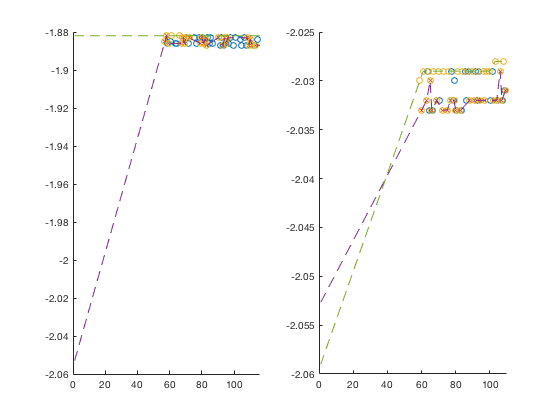

i=14;
tolerance=2.5;
try
    [unprocessed{i},tv{i},processed{i},tvp{i}]=createparam(path(i),indices(i,...
    1:lastnonempty(indices(i,:))), aux, inputname, trend, tolerance,pround);
catch ME
    if strcmp(ME.identifier,'MATLAB:griddedInterpolant:DegenerateGridErrId')
        warning('tolerance not OK.');
    else
        error(ME.message);
    end
end

2-14-ig folytatva a feldolgozást kitöltődnek az eredmények táblázatai és elkészülnek az ábrák. Ekkor szembetűnik, hogy az első 45 nyers adatot az algoritmus eldobja, ezzel számolni kell sweep-méréseknél pl. karakterisztikák felvételéhez. Továbbá az alsó becslőbe „agresszívebben” kerülnek a szűrt adatok, ez néha tartalmaz a felsőhöz tartozó, kiugró értékeket, emiatt ajánlott kiszámítani a becslők módusát.

processedmodes=modecounting(processed);
processedmodes

processedmodes = 1×1 cell array
    {2×12 double}


Ezzel egy mennyiség adatfeldolgozása véget ér. A pontosabb leolvasás érdekében a `modecounting` függvény nem egyszerűen módusokat számol, hanem ennek segítségével azonosítja a mért konstans mennyiség megfelelő becslőjét. Ennek működése alsó becslőkre lett tesztelve, ezért ezek tárolása következik.

## Mentés

if ~isfile('res/logp.mat')
save res/logp.mat aux indices inputname path processed ...
    processedmodes pround trend tv tvp unprocessed
else
    error('file res/logp.mat exists, aborting');
end

file res/logp.mat exists, aborting

Az egyik, pl. alsó becslő módusait érdemes .csv formátumban is elmenteni gyors eléréshez és LaTeX számára.

if ~isfile('res/logp.csv')
pm2=cell(1,length(processedmodes));
maxi=0;
for i=1:length(processedmodes)
    vector=processedmodes{1,i};
    if length(vector)>maxi
        maxi=length(vector);
    end
    pm2{1,i}=vector(1,:)';
end
    vector=nan(maxi,length(pm2));
    for j=1:length(pm2)
    vector(1:length(pm2{1,j}),j)=pm2{1,j};
    end
for i=1:maxi
    dlmwrite('res/logp.csv',vector(i,:),'-append','delimiter',',');
end
else
    error('file res/logp.csv exists, aborting');
end